# Lab2 

Ali Saeizadeh

810196477

## Lab2_1: Generating Digital Signal 

### 1. Random Sequence

#### A.


$$\left(X \sim \mathcal{N}(0,1) \rightarrow \sigma X+m \sim \mathcal{N}\left(m, \sigma^{2}\right)\right.$$



$$m = 10$$



$$\sigma^2 = 10
$$


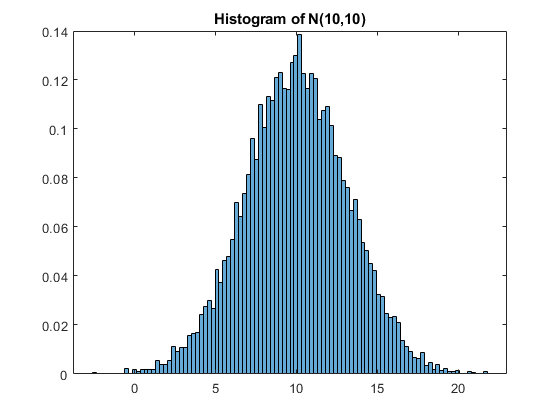

n_bin = 100;
N = 10000;
mean = 10;
variance = 10;
x1 = sqrt(variance) * randn(1,N) + mean;
histogram(x1,n_bin,"Normalization",'pdf');
title 'Histogram of N(10,10)'

#### B.

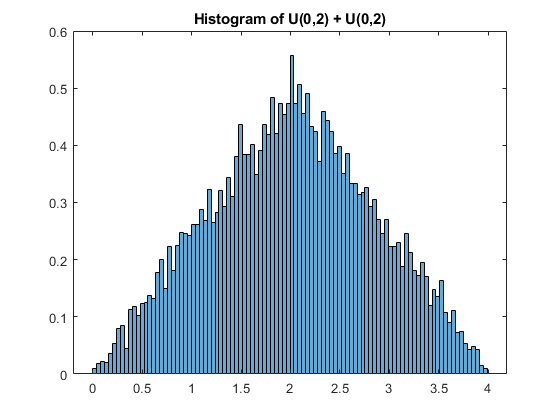

x2 = rand(1,N+1) * 2;
x3 = x2(2:end) + x2(1:end-1);
histogram(x3,n_bin,"Normalization",'pdf');
title 'Histogram of U(0,2) + U(0,2)'

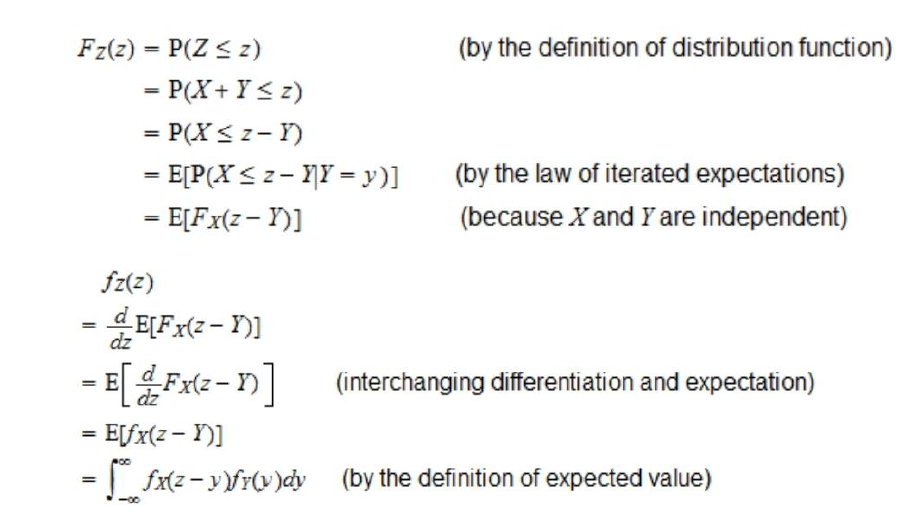

we know that convolution of two step function will produce triangle function.

#### C.

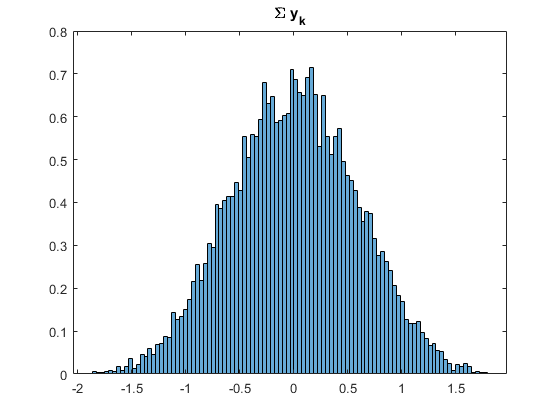

x4 =zeros(1,N);
for i=1:4
    x4 = x4 + (rand(1,N) - 0.5);
end
histogram(x4,n_bin,"Normalization",'pdf')
title('\Sigma y_k')

Just like last section, convolution of four step function or convolution of two triangle function results this shape.

**Central Limit Theorem: **If we sum up a lot of distribution, it will become a normal distribution.

### 2. Decreasing Sampling Rate

clear all
x = [-2,4,3,-6,5,-1,8];
y = dwnsmpl(x,2)

y =     -2     3     5     8


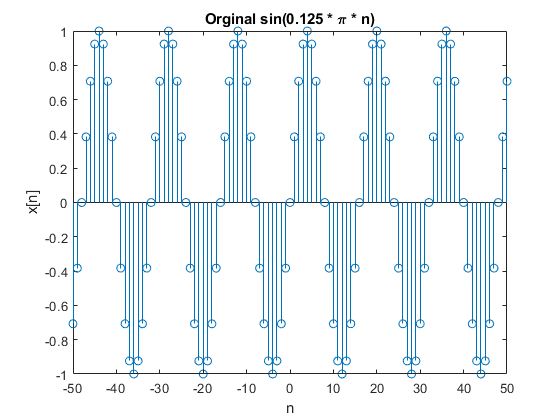

n = -50:1:50;
x = sin(0.125*pi*n);
y = dwnsmpl(x,4);
stem(n,x)
title('Orginal sin(0.125 * \pi * n)')
xlabel('n')
ylabel('x[n]')

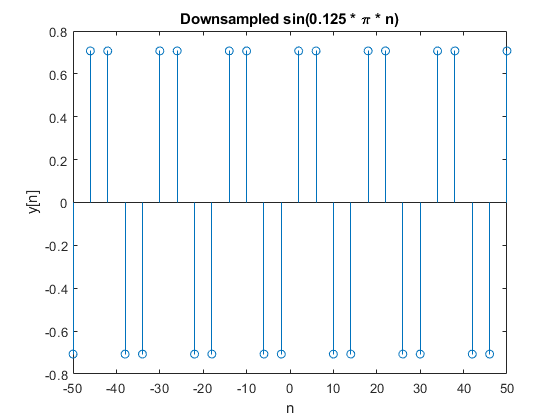


stem(dwnsmpl(n,4),y)
title('Downsampled sin(0.125 * \pi * n)')
xlabel('n')
ylabel('y[n]')

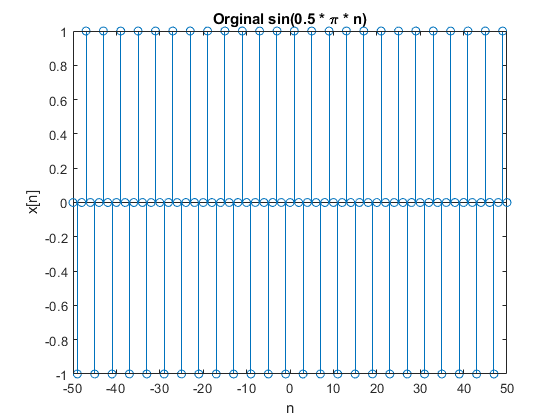

n = -50:1:50;
x = sin(0.5*pi*n);
y = dwnsmpl(x,4);
stem(n,x)
title('Orginal sin(0.5 * \pi * n)')
xlabel('n')
ylabel('x[n]')

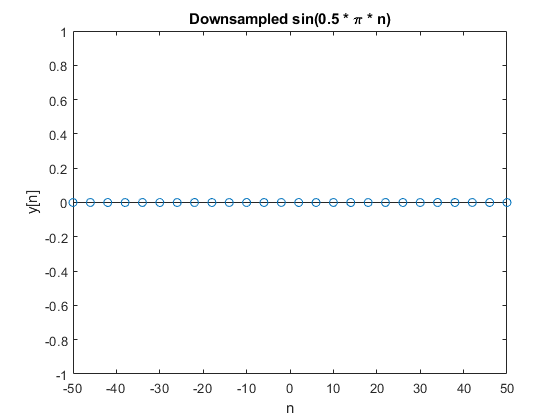

stem(dwnsmpl(n,4),y)
ylim([-1 1])
title('Downsampled sin(0.5 * \pi * n)')
xlabel('n')
ylabel('y[n]')

### 3. Increasing Sampling Rate

clear all
x = [-2,3,5,8];
y = upsmpl(x,2)

y =     -2     0     3     0     5     0     8     0


## Lab2_2

### 1

clear all
N = 101;
n = 0:N;
x = zeros(N+4,1);
x(4) = 1;
y1 = zeros(N+4,1);
for n = 4:N
   y1(n) = 0.5 * y1(n - 1) - 0.25 * y1(n - 2) + x(n) + 2 * x(n - 1) + x(n - 3);
end
a = [1 -0.5 0.25];
b = [1 2 0 1];
y2 = filter(b,a,x);
y1 

y1 =          0
         0
         0
    1.0000
    2.5000
    1.0000
    0.8750
    0.1875
   -0.1250
   -0.1094


y2

y2 =          0
         0
         0
    1.0000
    2.5000
    1.0000
    0.8750
    0.1875
   -0.1250
   -0.1094


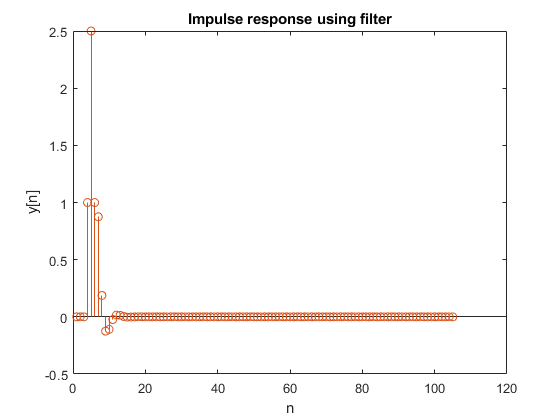

stem([y1,y2])
title('Impulse response using filter')
xlabel('n')
ylabel('y[n]')

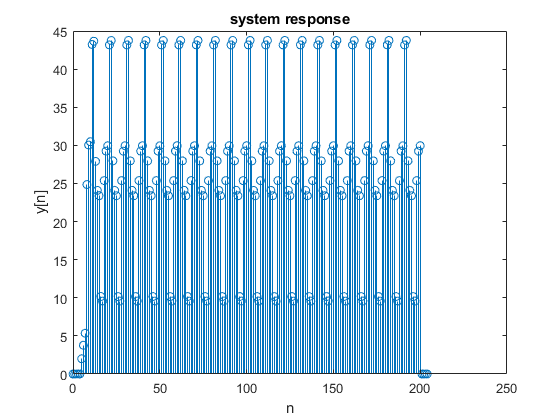

N = 201;
n = transpose(0:1:N+3);
x = 5 + 3 * cos(0.2 * pi * n) + 4 * sin(0.6 * pi * n);
x = (n > 4) .* (x);
y = zeros(N+4,1);
for k = 4:N
   y(k) = 0.5 * y(k - 1) - 0.25 * y(k - 2) + x(k) + 2 * x(k - 1) + x(k - 3);
end
stem(n,y)
title('system response')
xlabel('n')
ylabel('y[n]')

### 2

clear all
load('pulse.mat');
load('radar.mat')
r = corr_m(pulse,radar);

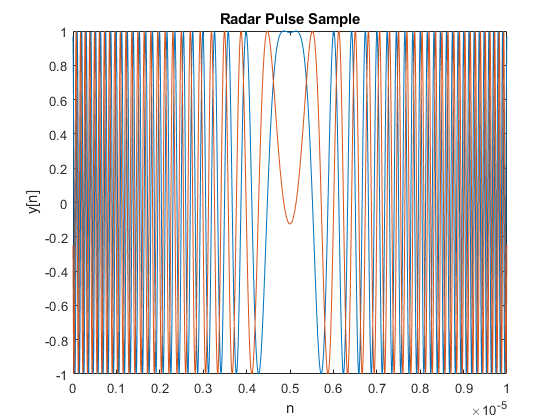

fs = 250e6;
t_pulse = 0:1/fs:(length(pulse)-1)/fs;
plot(t_pulse,real(pulse),t_pulse,imag(pulse))
title('Radar Pulse Sample')
xlabel('n')
ylabel('y[n]')

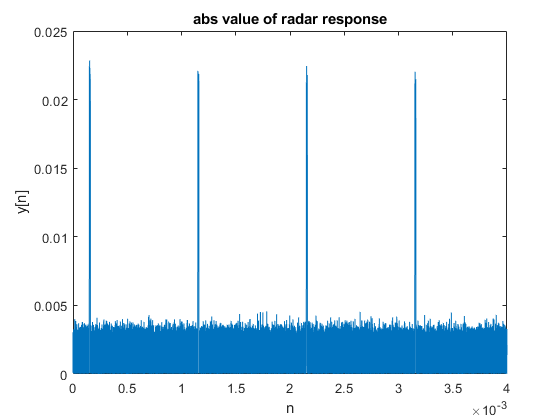

t_radar = 0:1/fs:(length(radar)-1)/fs;
plot(t_radar,abs(radar))
title('abs value of radar response')
xlabel('n')
ylabel('y[n]')

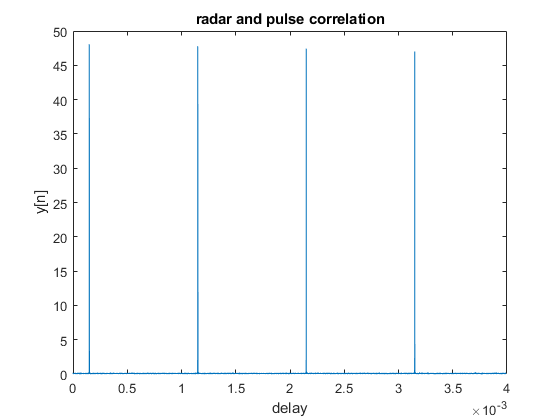

t_r = 0:1/fs:(length(r)-1)/fs;
plot(t_r,abs(r))
title('radar and pulse correlation')
xlabel('delay')
ylabel('y[n]')

Period ~= 1 ms

t = 0.00015 s

distance = c * t / 2 = 22.5

## Lab2_3

This input frequency has been chosen to have mimnimum spectral leakage.

clear all
A = 2

A = 2

f0 = (250 * 51 / 256) * 1e6 

f0 = 4.9805e+07

n_fft = 256

n_fft = 256

fs = 250e6;
freq_resolution = fs/n_fft

freq_resolution = 9.7656e+05

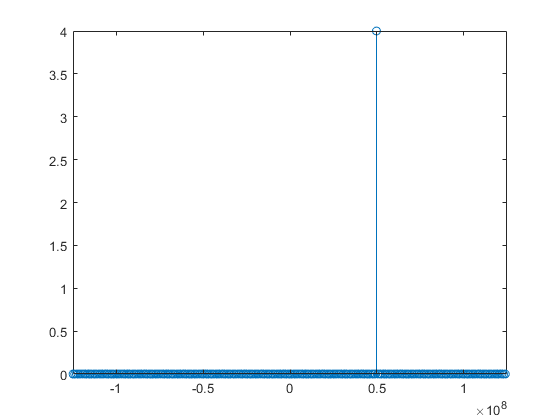

ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1j*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;A
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])

ratio = n_fft * ts * f0

ratio = 51

time_power = sum(abs(x).^2)/length(x)

time_power = 4

freq_power = sum(abs(Xf).^2)

freq_power = 4

R = 50

R = 50

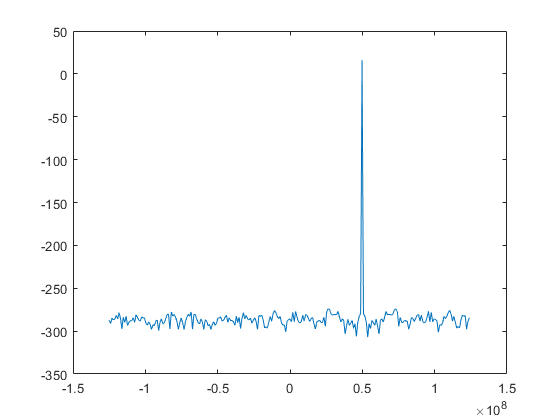

plot(freq, 10 * log10(abs(Xf).^2/(2*R))+30)

**Spectral Leakage[1]**

Any other type of operation creates new frequency components that may be referred to as **spectral leakage** in the broadest sense. Sampling, for instance, produces leakage, which we call aliases of the original spectral component. For Fourier transform purposes, sampling is modeled as a product between s(t) and a Dirac comb function. The spectrum of a product is the convolution between S(f) and another function, which inevitably creates the new frequency components. But the term 'leakage' usually refers to the effect of *windowing*, which is the product of s(t) with a different kind of function, the window function. Window functions happen to have finite duration, but that is not necessary to create leakage. Multiplication by a time-variant function is sufficient.

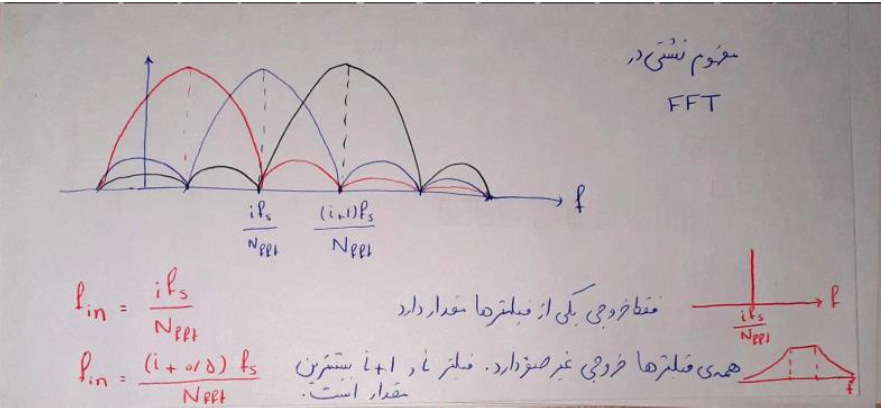

as it can be seen out input frequency have maximum spectral leakage

This input frequency has been chosen to have maximum spectral leakage.

A = 2

A = 2

f0 = (250 * 51.5 / 256 ) * 1e6

f0 = 5.0293e+07

n_fft = 256

n_fft = 256

fs = 250e6;
freq_resolution = fs/n_fft

freq_resolution = 9.7656e+05

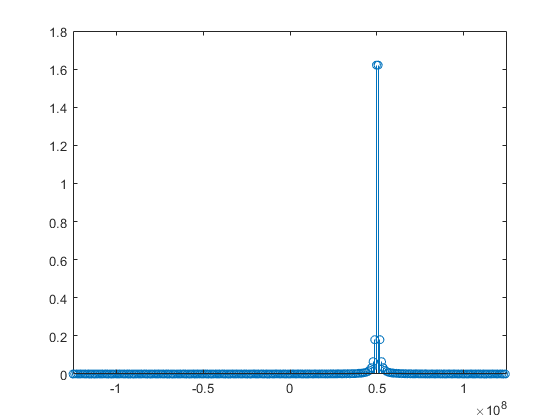

ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])

ratio = n_fft * ts * f0

ratio = 51.5000

time_power = sum(abs(x).^2)/length(x)

time_power = 4

freq_power = sum(abs(Xf).^2)

freq_power = 4

R = 50

R = 50

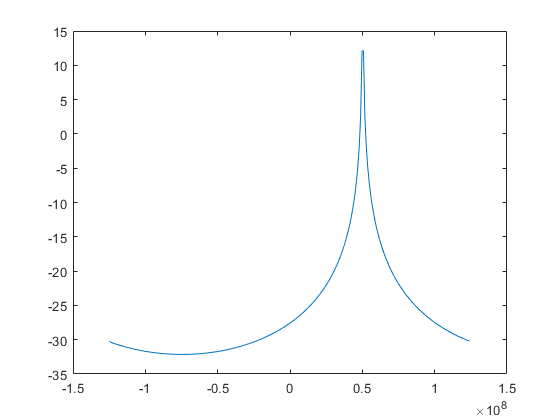

plot(freq, 10 * log10(abs(Xf).^2/(2*R))+30)

A = 2

A = 2

f0 = (250 * 51 / 256) * 1e6 

f0 = 4.9805e+07

n_fft = 512

n_fft = 512

fs = 250e6;
freq_resolution = fs/n_fft

freq_resolution = 4.8828e+05

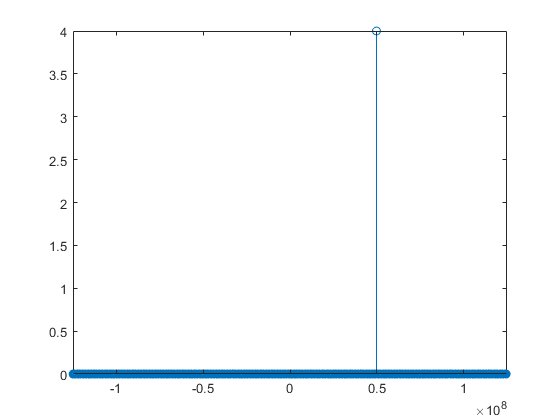

ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])

ratio = n_fft * ts * f0

ratio = 102

time_power = sum(abs(x).^2)/length(x)

time_power = 4

freq_power = sum(abs(Xf).^2)

freq_power = 4

R = 50

R = 50

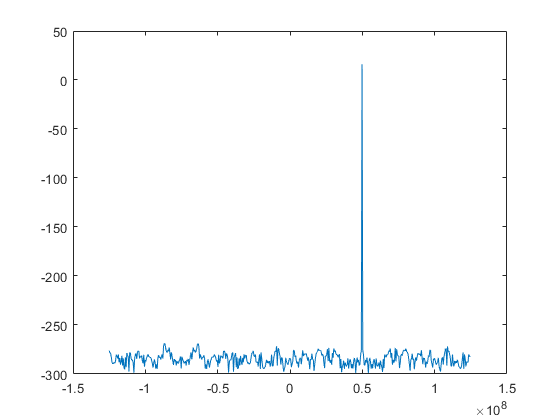

plot(freq, 10 * log10(abs(Xf).^2/(2*R))+30)

A = 2

A = 2

f0 = -(250 * 51 / 256 ) * 1e6 

f0 = -4.9805e+07

n_fft = 512

n_fft = 512

fs = 250e6;
freq_resolution = fs/n_fft

freq_resolution = 4.8828e+05

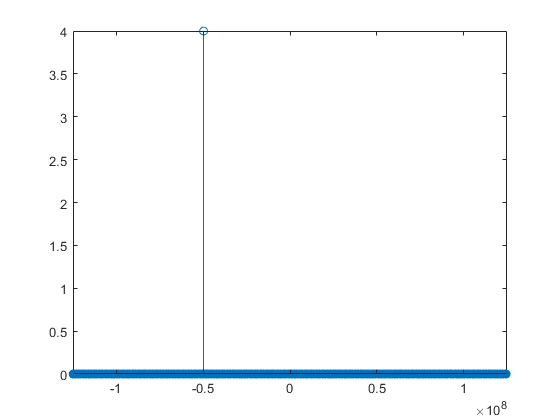

ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])

ratio = n_fft * ts * f0

ratio = -102

time_power = sum(abs(x).^2)/length(x)

time_power = 4

freq_power = sum(abs(Xf).^2)

freq_power = 4

R = 50

R = 50

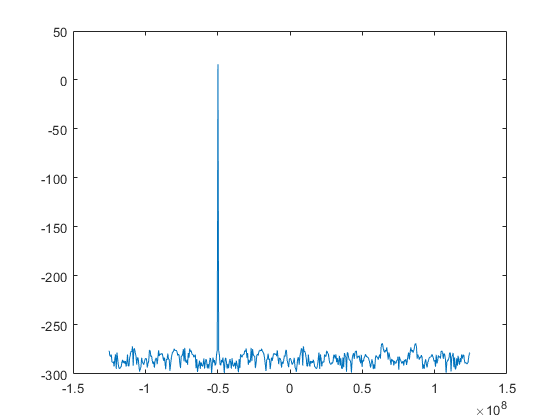

plot(freq, 10 * log10(abs(Xf).^2/(2*R))+30)

A = 4

A = 4

f0 = (250 * 153 / 256 ) * 1e6 

f0 = 1.4941e+08

n_fft = 512

n_fft = 512

fs = 250e6;
freq_resolution = fs/n_fft

freq_resolution = 4.8828e+05

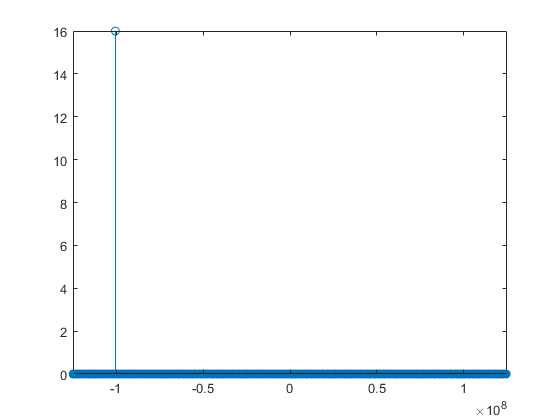

ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])

ratio = n_fft * ts * f0

ratio = 306

time_power = sum(abs(x).^2)/length(x)

time_power = 16

freq_power = sum(abs(Xf).^2)

freq_power = 16

R = 50

R = 50

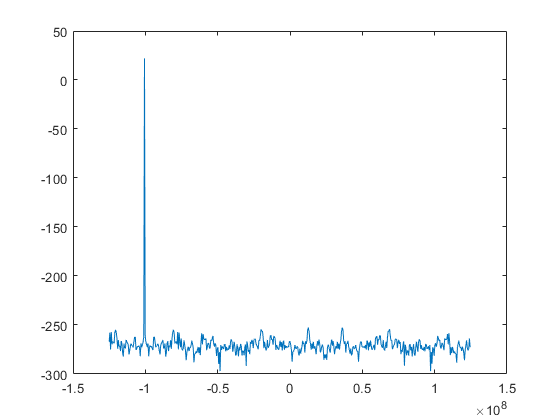

plot(freq, 10 * log10(abs(Xf).^2/(2*R))+30)

Frequency that is higher than sampling frequency will result this spectrum

153 - 125

Effect of n_fft on frequency resolution

By increasing n_fft we will have more frequency resolution 

frequency resolution = fs/n_fft

A = 2

A = 2

f0 = (250 * 51.5 / 256 ) * 1e6 

f0 = 5.0293e+07

n_fft = 256

n_fft = 256

fs = 250e6;
freq_resolution = fs/n_fft

freq_resolution = 9.7656e+05

ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])


A = 2

A = 2

f0 = (250 * 51.5 / 256 ) * 1e6 

f0 = 5.0293e+07

n_fft = 512

n_fft = 512

fs = 250e6;
freq_resolution = fs/n_fft

freq_resolution = 4.8828e+05

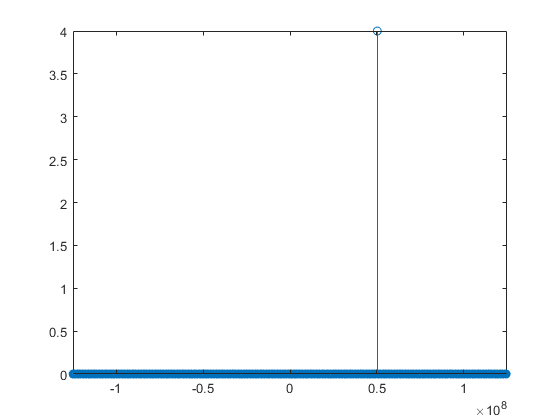

ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])


A = 2

A = 2

f0 = (250 * 51.25 / 256 ) * 1e6 

f0 = 5.0049e+07

n_fft = 512

n_fft = 512

fs = 250e6;
freq_resolution = fs/n_fft

freq_resolution = 4.8828e+05

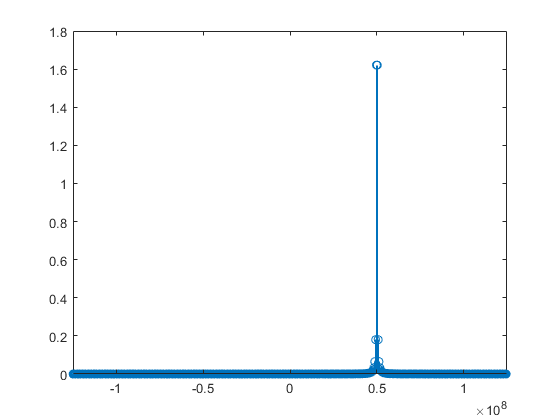

ts = 1/fs;
t = (0:n_fft-1);
freq = (0:n_fft-1)/n_fft * fs - fs/2;
x = A*exp(1i*2*pi*t*f0*ts);
Xf = fftshift(fft(x, n_fft))/n_fft;
stem(freq, abs(Xf).^2)
xlim([-125e6,125e6])